clear;close all;
x = importdata("pressure.txt");
X = readmatrix("data_08092023_x242y56_exp1.xlsx");

t = x(1:269,1)*4.9/67.25;
s51 = x(1:269,2);

Time = X(:,1);
Donne = X(:,2);
ETAT = X(:,3);

index = find(ETAT);

%% Paramètre de l'aquisition reçu
fs = 1000;            % Sampling frequency                    
T = 1/fs;             % Sampling period       
L = numel(Donne);     % Length of signal

figure("Name","Simulation");
plot(t,s51);

xlabel("t");
ylabel("Pressure coefficient");

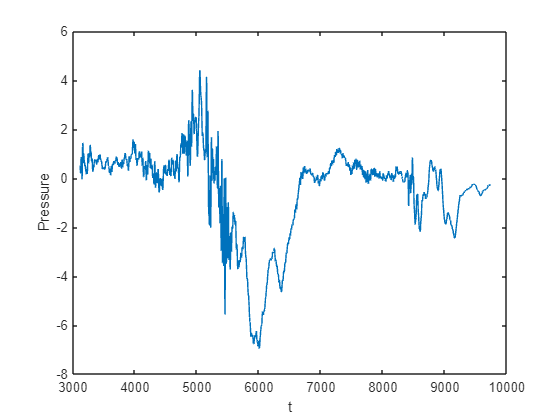

%% Supression de la composante continue (la moyenne)
Donne0 = Donne - mean(Donne);

%% FFT
Y = fft(Donne0);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(L/2))/L;

%% Signal processing
%LP by BUTTER
fc1 = 40;
[b,a] = butter(2,fc1/(fs/2),'low');
filtrees=filtfilt(b,a,Donne0);

figure
plot(Time(index), -filtrees(index))
xlabel("t");
ylabel("Pressure");

figure("Name","Diff for sensor 1");
plot(t,s11*0.5*1000*0.089*0.089);

Unrecognized function or variable 's11'.

hold on;
plot(T,rs1-mean(rs1));

legend("Simulation","Sensor");
xlabel("t");
ylabel("Pressure");
hold off;

figure("Name","Diff for sensor 2");
plot(t,s21*0.5*1000*0.089*0.089);
hold on;
plot(T,rs5-mean(rs5));

legend("Simulation","Sensor");
xlabel("t");
ylabel("Pressure");
hold off;

figure("Name","Diff for sensor 4");
plot(t,s41*0.5*1000*0.089*0.089);
hold on;
plot(T,rs4-mean(rs4));

legend("Simulation","Sensor");
xlabel("t");
ylabel("Pressure");
hold off;

figure("Name","Diff for sensor 5");
plot(t,s51*0.5*1000*0.089*0.089);
hold on;
plot(T,rs2-mean(rs2));

legend("Simulation","Sensor");
xlabel("t");
ylabel("Pressure");
hold off;